## ROS2 Package ID

folderpath = fullfile(pwd,"EECE5554/LAB4/src/") % Access folder & build packages
ros2genmsg(folderpath) % This probably isnt doing anything

bagselect2=ros2bagreader("EECE5554/LAB4/data/data_driving2") % Access data

## Data Extraction

fields = readMessages(bagselect2);
bSel = select(bagselect2,"Topic","/imu");
%imu = readMessages(bSel,'DataFormat','struct');
a = fields{1};
IMUmsgs= readMessages(bSel);
a2 = IMUmsgs{1}

a2 = struct with fields:
    MessageType: 'imu_interface/IMUmsg'
         header: [1×1 struct]
            imu: [1×1 struct]
      mag_field: [1×1 struct]
         rawstr: '$VNYMR,+034.865,-005.825,-011.625,-00.0421,-00.0219,+00.1037,+00.503,-00.463,-09.337,-00.003607,-00.006419,+00.055982*63'



fields2 = readMessages(bagselect2);
bSel2 = select(bagselect2,"Topic","/gps");
%imu = readMessages(bSel,'DataFormat','struct');
b = fields{1};
GPSmsgs= readMessages(bSel2);
b2 = GPSmsgs{1};

testPoint = cellfun(@(m) struct(m.header.stamp),fields);
gyroPoints = cellfun(@(m) struct(m.imu.angular_velocity),IMUmsgs);
accelPoints = cellfun(@(m) struct(m.imu.linear_acceleration),IMUmsgs);
orientPoints = cellfun(@(m) struct(m.imu.orientation),IMUmsgs);
magPoints = cellfun(@(m) struct(m.mag_field.magnetic_field),IMUmsgs);

lati = cellfun(@(m) double(m.latitude),GPSmsgs);
long = cellfun(@(m) double(m.longitude),GPSmsgs);
utc = cellfun(@(m) string(m.utc),GPSmsgs);
%alt = cellfun(@(m) string(m.altitude),GPSmsgs)
%alti = str2int2(extract(alt,))

VNYMR = cellfun(@(m) string(m.rawstr),IMUmsgs);

Error using cellfun
string output type is not supported. Set 'UniformOutput' to false.

%plot(imuPoints)

%gyroData = gyroPoints{:,[2 3 4]}
gyroPoints(1)
xGyro = arrayfun(@(m) double(m.x),gyroPoints);
yGyro = arrayfun(@(m) double(m.y),gyroPoints);
zGyro = arrayfun(@(m) double(m.z),gyroPoints);


accelPoints(1)
xAccel = arrayfun(@(m) double(m.x),accelPoints);
yAccel = arrayfun(@(m) double(m.y),accelPoints);
zAccel = arrayfun(@(m) double(m.z),accelPoints);

orientPoints(1)
xOrient = arrayfun(@(m) double(m.x),orientPoints);
yOrient = arrayfun(@(m) double(m.y),orientPoints);
zOrient = arrayfun(@(m) double(m.z),orientPoints);
wOrient = arrayfun(@(m) double(m.w),orientPoints);

magPoints(1)
xMag = arrayfun(@(m) double(m.x),magPoints)*10^4;
yMag = arrayfun(@(m) double(m.y),magPoints)*10^4;
zMag = arrayfun(@(m) double(m.z),magPoints)*10^4;

## Forward Velocity Estimate Accelerometer

FwdAccel = (xAccel-0.475)

FwdAccel =     0.0280
    0.0740
    0.0330
    0.1010
    0.0460
    0.0530
    0.0840
    0.0990
    0.0870
    0.1160


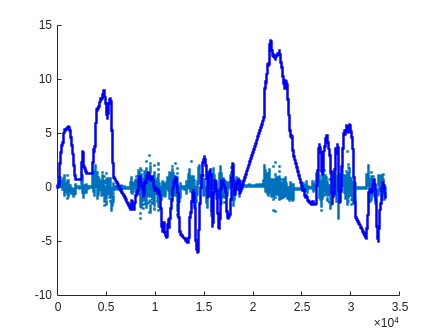

FwdVelo = cumtrapz(FwdAccel)*(2*10^-2);
figure
hold on
plot(FwdAccel,'.')
plot(FwdVelo,'b.')

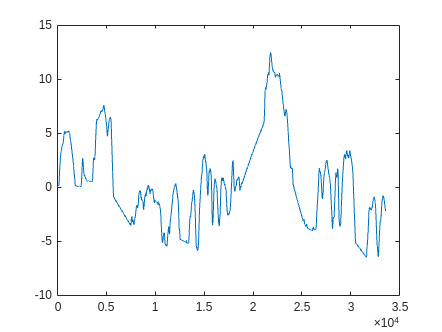


alph = 0.9999;
FVimu = zeros(size(FwdVelo));
FVimu(1) = FwdVelo(1);  % Initialize
for i = 2:length(FwdVelo)
    FVimu(i) = alph * (FVimu(i-1) + FwdVelo(i) - FwdVelo(i-1));
end

figure
plot(FVimu)

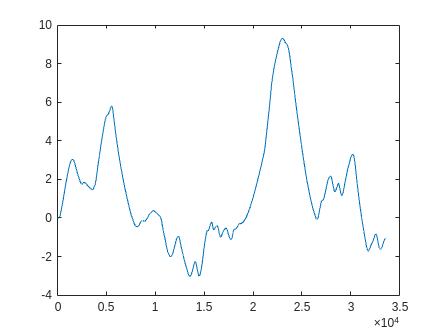


% veo = FwdVelo;   
% alpha = 0.001;   % Smoothing factor (0 < alpha < 1), smaller = smoother
% 
% % Preallocate output array
% FVimu = zeros(size(veo));
% FVimu(1) = veo(1);  % Initialize with first value
% 
% % Apply low-pass filter
% for i = 2:length(veo)
%     FVimu(i) = alpha * veo(i) + (1 - alpha) * FVimu(i-1);
% end
% 
% figure
% plot(FVimu)

## Forward Velocity Estimate GPS

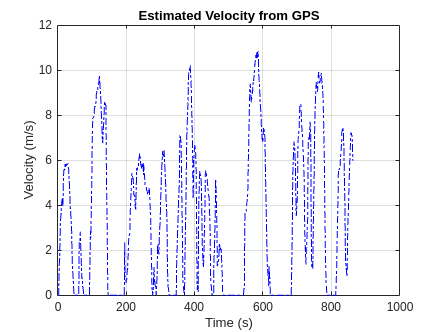


% Example data
lat = lati;   % Latitude in degrees
lon = long;   % Longitude in degrees

hh = str2double(extractBetween(utc, 1, 2));
mm = str2double(extractBetween(utc, 3, 4));
ss = str2double(extractBetween(utc, 5, 10));

baseDate = datetime('2024-01-01');  % dummy date
utc_time = baseDate + hours(hh) + minutes(mm) + seconds(ss);
t = seconds(utc_time - utc_time(1));

% Earth's radius in meters
R = 6371000;

% Convert degrees to radians
lat_rad = deg2rad(lat);
lon_rad = deg2rad(lon);

% Calculate differences
dlat = diff(lat_rad);
dlon = diff(lon_rad);

% Midpoint latitude for each segment
lat_mid = lat_rad(1:end-1) + dlat / 2;

% Haversine-like flat approximation
dx = R * dlon .* cos(lat_mid);
dy = R * dlat;

% Use these to compute velocity
dt = diff(t);  % t is from your converted UTC timestamps
v = sqrt(dx.^2 + dy.^2) ./ dt;
v = [NaN; v];

figure
plot(t, v, 'b-.');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Estimated Velocity from GPS');
grid on;

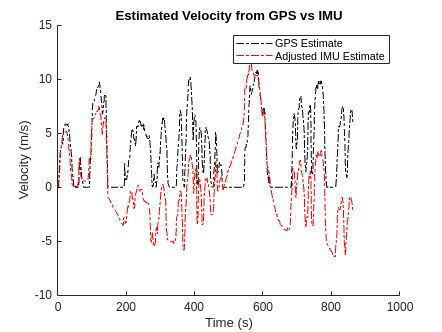



x1 = linspace(0, 10, 605);  % 600 data points
x2 = linspace(0, 10, 33566);  % 35000 data points


% Rescale the larger dataset to match the range of the smaller dataset
FVimu_scale = interp1(x2, FVimu, x1, 'linear');  

figure
hold on
plot(t,v,'k-.')
plot(t,FVimu_scale,'r-.')
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Estimated Velocity from GPS vs IMU');
legend('GPS Estimate','Adjusted IMU Estimate')

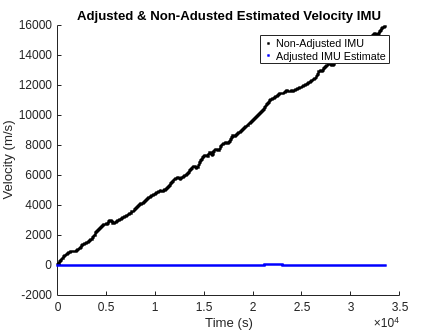


figure
hold on
plot(cumtrapz(xAccel),'k.')
plot(FVimu,'b.')
xlabel('Time (s)');
ylabel('Velocity (m/s)');
title('Adjusted & Non-Adusted Estimated Velocity IMU');
legend('Non-Adjusted IMU','Adjusted IMU Estimate')

where did the backvround go